rosenbrock = @(x) log(1+100*(x(:,2)-x(:,1).^2).^2+(1-x(:,1)).^2);
%vektorielle Darstellung

x = linspace(0,2,30);
y = linspace(0,2,30);
[X,Y] = meshgrid(x,y);
Z = rosenbrock([X(:), Y(:)]);
Z = reshape(Z,size(X))

Z =     0.6931    0.6255    0.5763    0.5946    0.7436    1.0449    1.4529    1.9020    2.3482    2.7717    3.1662    3.5316    3.8699    4.1839    4.4763    4.7495    5.0057    5.2469    5.4745    5.6900    5.8947    6.0894    6.2751    6.4527    6.6227    6.7858    6.9425    7.0934    7.2387    7.3790
    0.9065    0.8238    0.6894    0.5291    0.4249    0.5180    0.8710    1.3763    1.9086    2.4112    2.8698    3.2853    3.6627    4.0075    4.3244    4.6175    4.8899    5.1445    5.3834    5.6084    5.8211    6.0227    6.2145    6.3972    6.5718    6.7389    6.8992    7.0532    7.2015    7.3443
    1.3616    1.2921    1.1496    0.9298    0.6454    0.3822    0.3747    0.7758    1.3793    1.9825    2.5257    3.0059    3.4323    3.8144    4.1603    4.4763    4.7671    5.0366    5.2879    5.5232    5.7446    5.9537    6.1519    6.3402    6.5196    6.6910    6.8550    7.0123    7.1635    7.3089
    1.8375    1.7839    1.6625    1.4636    1.1741    0.7900    0.3859    0.2897    0.7662   

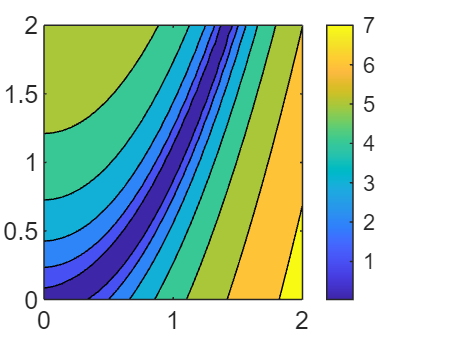

contourf(X,Y,Z)
colorbar

surf(X,Y,Z)
%colorbar
%mesh(X,Y,Z) würde in 3D nur das Gitternetz anzeigen.

punkt=fminsearch(rosenbrock,[0 0])%[Startpunkt]

punkt =     1.0000    1.0000


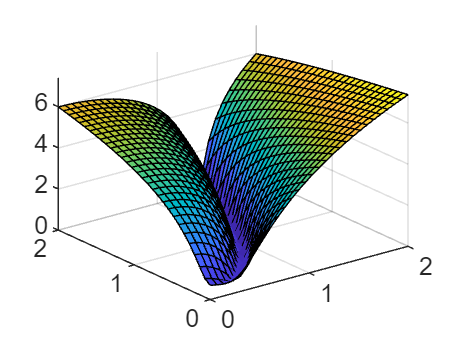

hold on
plot(punkt(1),punkt(2),'ro')
hold off

Einschränkung auf den Einheitskreis:

%nicht mehr in VL zum Funktionieren gebracht
rosenbrock_limited = @(x) rosenbrock(x) + piecewise(norm(x)<=1,0,norm(x)>1,norm(x));
punkt_limited = fminsearch(rosenbrock_limited,[0 0]);

Incorrect number or types of inputs or outputs for function 'piecewise'.

Error in LiveScript Höhenlinien (line 19)
rosenbrock_limited = @(x) rosenbrock(x) + piecewise(norm(x)<=1,0,norm(x)>1,norm(x));

Error in fminsearch (line 201)
fv(:,1) = funfcn(x,varargin{:});

plot(punkt_limited(1),punkt_limited(2),'wo')
hold off